close all; clear; clc;

# DSv1 Thrust Curve Secondary Test

**file name**: DSv1_TM15d_20180809.mlx

**keywords:** 

**date of test:** 20180809

**file created by:** YYYYMMDD, NAME

**last updated on:** YYYYMMDD

**primary purpose:** Analyze one battery as external power source. 12 volts, 75 amp hours

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00226591241963588;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('DSv1_TM15d.mat');
time = DSv1_TM15d(:,1);                       % [sec]
PWM = DSv1_TM15d(:,2);                        % [micro sec]
Q = DSv1_TM15d(:,4);                          % [ft.lbf]
T = DSv1_TM15d(:,5);                          % [lbf]
Input_V = DSv1_TM15d(:,6);                    % [Volts]
Input_A = DSv1_TM15d(:,7);                    % [Amps]
rot_speed_rpm = DSv1_TM15d(:,8);              % [rad/sec]
% convert to RPM for plotting purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [RPM]
P_in_W = DSv1_TM15d(:,9);                     % [Watts]
P_out_W = DSv1_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = DSv1_TM15d(:,11);                 % [%]
Prop_Eff = DSv1_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = DSv1_TM15d(:,13);               % [lbf/Watts]  
ESC_Temp = DSv1_TM15d(:,14);                  % [F]
Motor_Temp = DSv1_TM15d(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

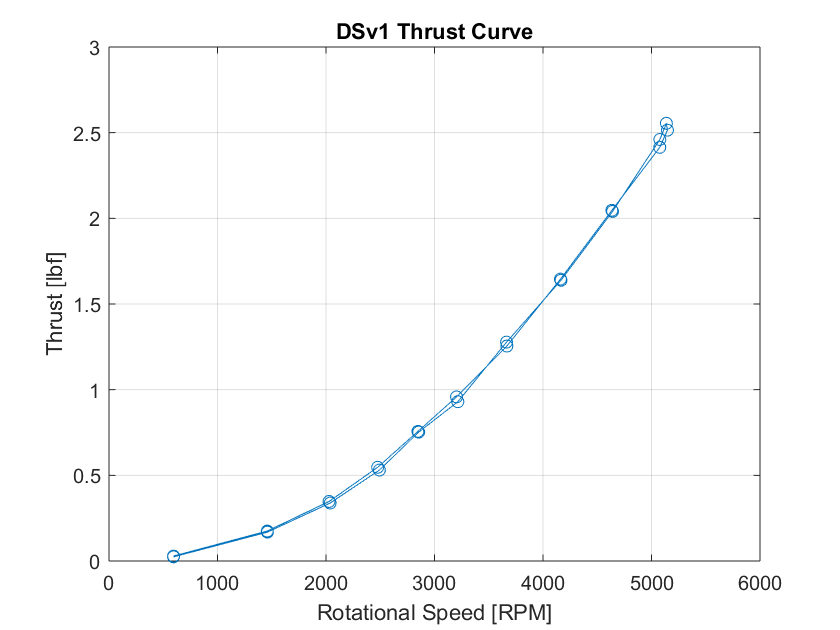

figure(1)
plot(rot_speed_rpm, T, 'o-'); title('DSv1 Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

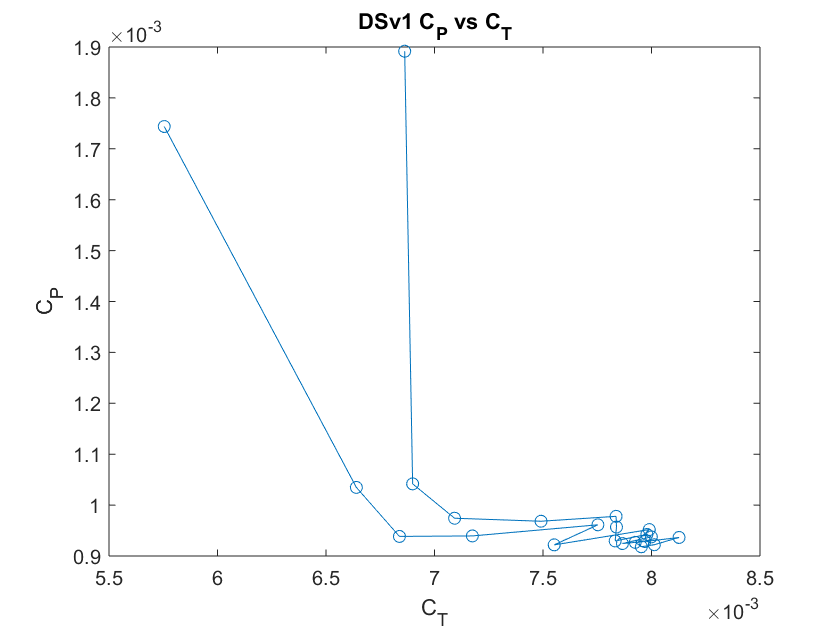


figure(2)
plot(C_T, C_P,'o-');
title('DSv1 C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

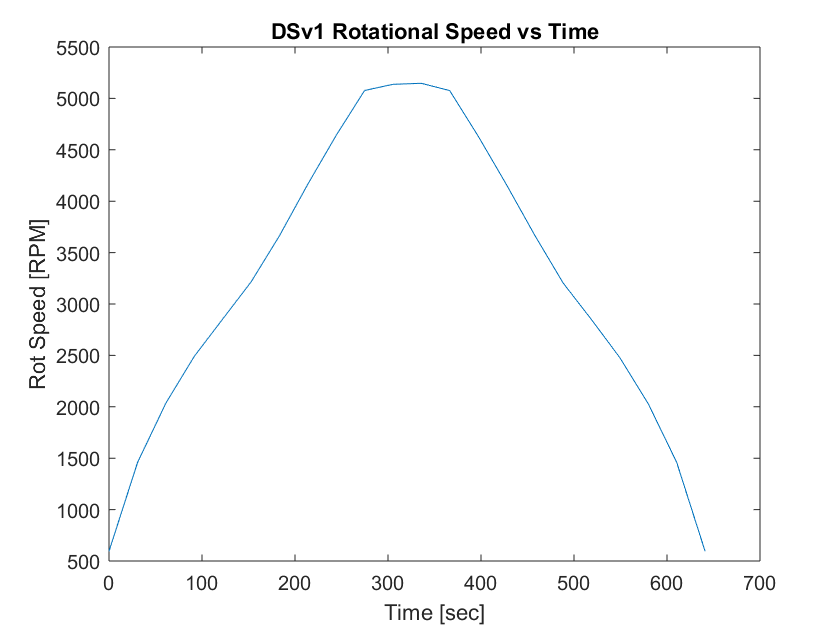


figure(3)
plot(time, rot_speed_rpm); title('DSv1 Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

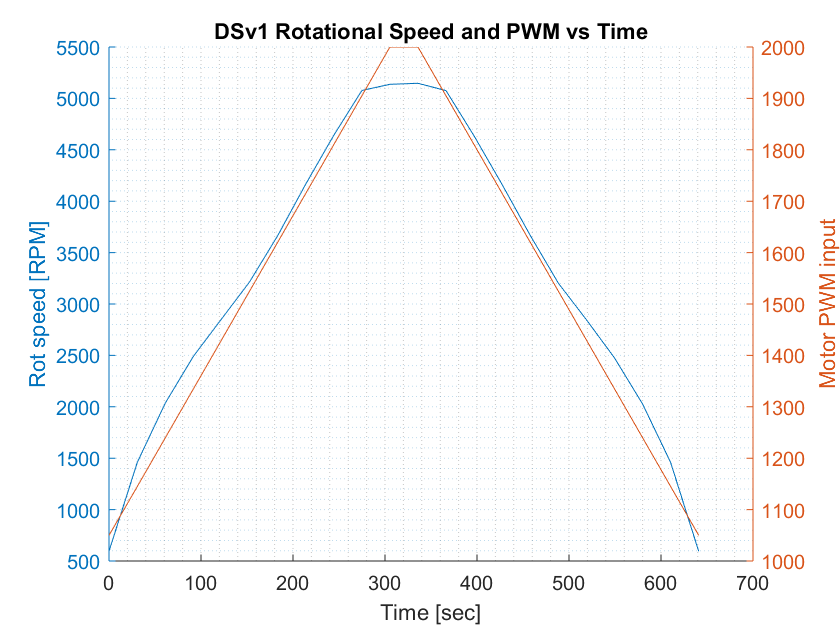


figure(4)
hold on
yyaxis left
plot(time, rot_speed_rpm);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM);
ylabel('Motor PWM input');
title('DSv1 Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

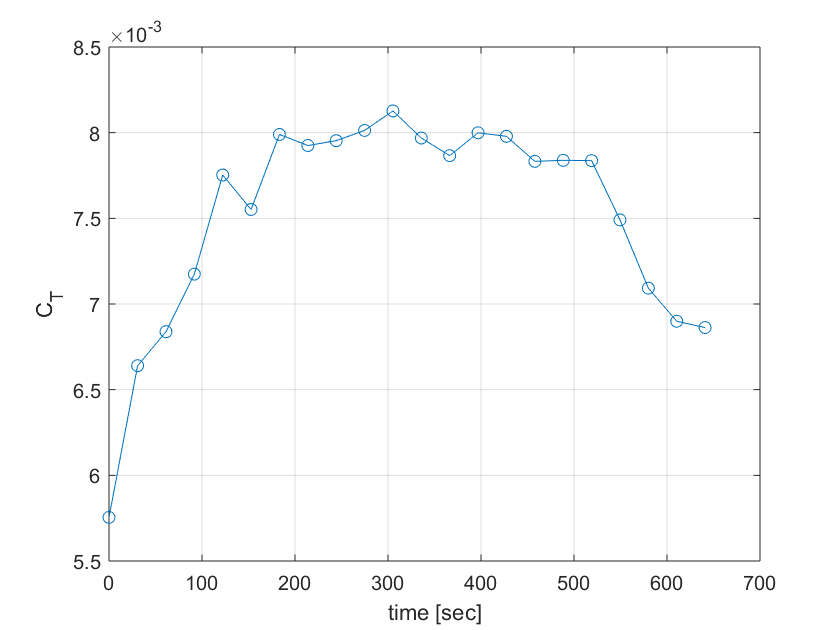



figure(5)
plot(time, C_T, 'o-'); grid('on');
xlabel('time [sec]'); ylabel('C_T');

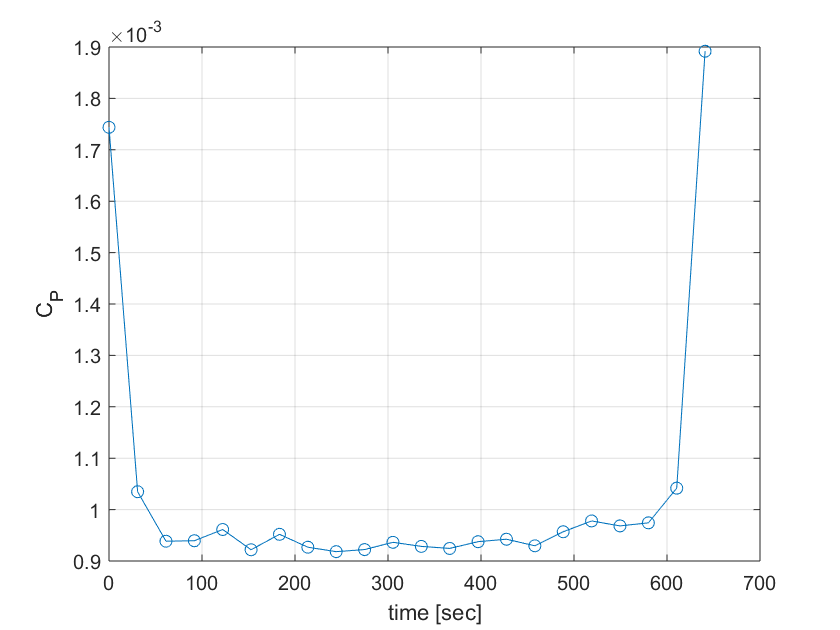



figure(6)
plot(time, C_P, 'o-'); grid('on');
xlabel('time [sec]'); ylabel('C_P');

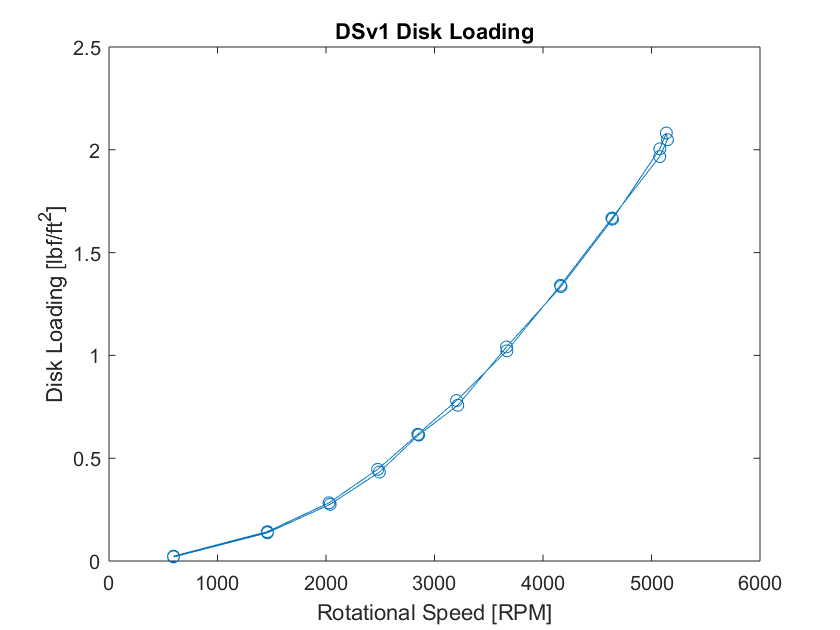


figure(7)
plot(rot_speed_rpm, disk_loading, 'o-'); title('DSv1 Disk Loading');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')